# ece 278c hw 6 multi frequency gpr imaging

## (1) read and normalize data

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["x_0_", "Var2"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Import the data
given_data = readtable("/Users/tyler/Documents/UCSB/278C/hw6/code/data.txt", opts);

% Clear temporary variables
clear opts

% Display results
given_data

given_data = 25799×2 table
     x_0_      Var2 
    ______    ______

      6924      2208
     -5412      9176
     -8508     -1176
     -1564     -9472
      9012     -9252
     15352       312
      7972     12560
     -6360     11944
    -10980       -96
     -6108     -8344
      2772    -12768
     12928     -9536
     17796       168
     12204     12488
     -2544     15280
    -11304      4444


given_data = table2array(given_data);
W = 128;
T = 200;
data_tot = zeros([W T]);
r = 0; c = 1;
for i = 1:size(given_data,1)
    r = r + 1;
    if ~isnan(given_data(i,1))
        data_tot(r,c) = given_data(i,1) + 1j*given_data(i,2); 
    else
        c = c + 1;
        r = 0;
    end
end

max_mag = 0;
angles = zeros(size(data_tot));
mags = zeros(size(data_tot));
for i = 1:size(data_tot,1)
    for j = 1:size(data_tot,2)
        angles(i,j) = angle(data_tot(i,j));
        mags(i,j) = abs(data_tot(i,j));
        if mags(i,j) > max_mag
            max_mag = mags(i,j);
        end
    end
end
mags = mags./max_mag;

data_tot_norm = zeros(size(data_tot));
for i = 1:size(data_tot,1)
    for j = 1:size(data_tot,2)
        [a,b] = pol2cart(angles(i,j),mags(i,j));
        data_tot_norm(i,j) = a - 1j*b;
    end
end
data_tot = data_tot_norm;

data_tot = F;
for i = 1:size(data_tot,1)
    for j = 1:size(data_tot,2)
        data_tot(i,j) = data_tot(i,j) - 2*imag(data_tot(i,j))*1j;
    end
end

## (2) setup

% params
spacing = 0.0213;
span = (T-1)*spacing;
xbound = [0 span];
ybound = [-0.25 0];
dist = 0;

% create array of wavelengths
wavelengths = zeros([1 W]);
freqs = linspace(0.976*10^9,2*10^9,W);
permittivity = 6;
c = 299792458;
for n = 1:W
    wavelengths(n) = c/(freqs(n)*sqrt(permittivity));
end

## (3) build arrays of the cumulatively-built wavefield and spectrum

h_tot = zeros(0);
h_sum = zeros(0);
spectrum_tot = zeros(0);
spectrum_sum = zeros(0);
for i = 1:T
    data = data_tot(:,i);
    xcoor = (i-1)*spacing;
    ycoor = dist;
    px = ones([1 W])*xcoor;
    py = ones([1 W])*ycoor;
    [x,y,h,spectrum,fx] = waveguide_generation(wavelengths,spacing/8,spacing/4,xbound,ybound,px,py,data);
    if i == 1
        h_sum = h;
        spectrum_sum = spectrum;
    else
        h_sum = h_sum + h;
        spectrum_sum = spectrum_sum + spectrum;
    end
    h_tot = [h_tot; h_sum];
    spectrum_tot = [spectrum_tot; spectrum_sum];
    disp('n = '+string(i)+' of '+string(T));
end

n = 1 of 200
n = 2 of 200
n = 3 of 200
n = 4 of 200
n = 5 of 200
n = 6 of 200
n = 7 of 200
n = 8 of 200
n = 9 of 200
n = 10 of 200
n = 11 of 200
n = 12 of 200
n = 13 of 200
n = 14 of 200
n = 15 of 200
n = 16 of 200
n = 17 of 200
n = 18 of 200
n = 19 of 200
n = 20 of 200
n = 21 of 200
n = 22 of 200
n = 23 of 200
n = 24 of 200
n = 25 of 200
n = 26 of 200
n = 27 of 200
n = 28 of 200
n = 29 of 200
n = 30 of 200
n = 31 of 200
n = 32 of 200
n = 33 of 200
n = 34 of 200
n = 35 of 200
n = 36 of 200
n = 37 of 200
n = 38 of 200
n = 39 of 200
n = 40 of 200
n = 41 of 200
n = 42 of 200
n = 43 of 200
n = 44 of 200
n = 45 of 200
n = 46 of 200
n = 47 of 200
n = 48 of 200
n = 49 of 200
n = 50 of 200
n = 51 of 200
n = 52 of 200
n = 53 of 200
n = 54 of 200
n = 55 of 200
n = 56 of 200
n = 57 of 200
n = 58 of 200
n = 59 of 200
n = 60 of 200
n = 61 of 200
n = 62 of 200
n = 63 of 200
n = 64 of 200
n = 65 of 200
n = 66 of 200
n = 67 of 200
n = 68 of 200
n = 69 of 200
n = 70 of 200
n = 71 of 200
n = 72 of 200
n

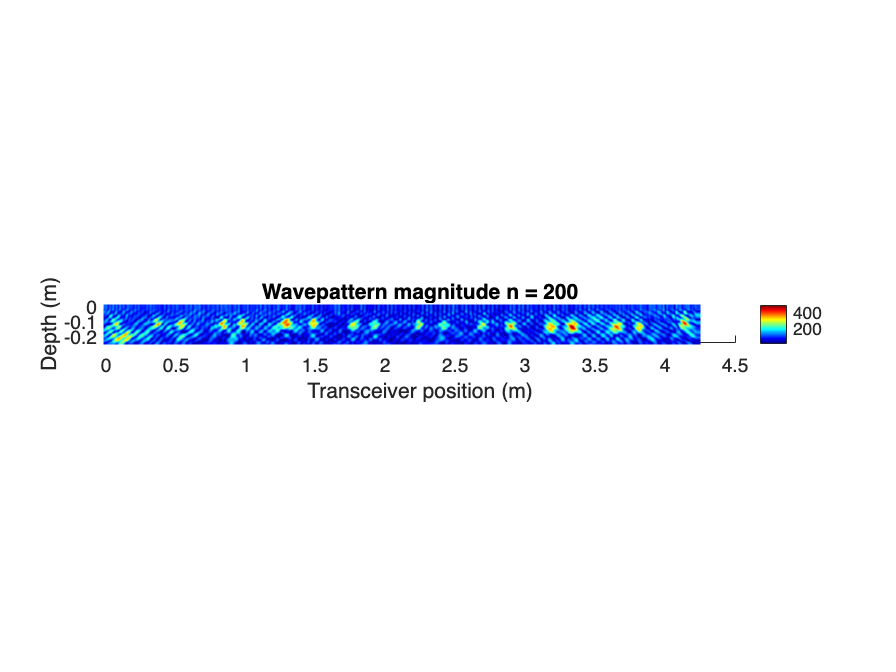

% num_yticks = 4;
% yticks = zeros([1 num_yticks]);
% for i = 1:num_yticks+1
%     yticks(num_yticks-(i-1)+1) = round((i-1)*-0.26/num_yticks,2);
% end
scatter(x,y,10,abs(h_tot(T,:)),'square','filled')
fontsize(12,"points")
title('Wavepattern magnitude n = ' + string(T))
xlabel('Transceiver position (m)'); ylabel('Depth (m)');
% yticklabels(yticks)
ratio = span/-ybound(1);
pbaspect([ratio 1 1])
colormap(jet)
colorbar

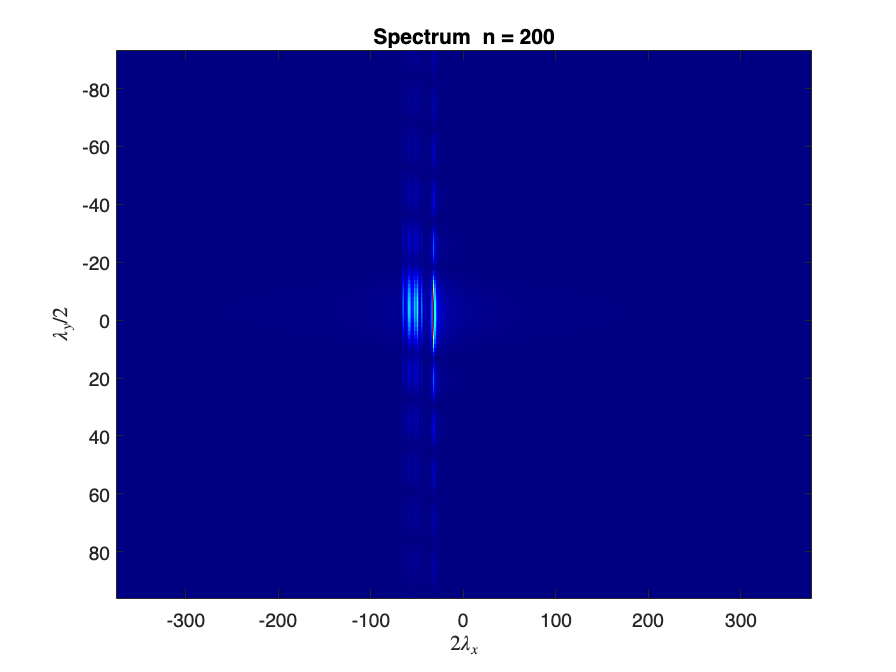

figure;
start_index = 1+((4-1)*size(spectrum_tot,2));
spec = abs(fftshift(spectrum_tot(start_index:start_index+size(spectrum_tot,2)-1,:)));
ht = size(spec,1); wt = size(spec,2);
imagesc(fx,fx(1,ht*3/8:ht*5/8),spec(ht*3/8:ht*5/8,:));
fontsize(12,"points")
title('Spectrum  n = ' + string(i)')
xlabel('$2\lambda_x$','Interpreter','latex');
ylabel('$\lambda_y/2$','Interpreter','latex');
colormap(jet)

## (4) save wavefield and spectra as jpg images

cd ..; cd images5;

for i = 1:T
    % plot wavefield
    f = figure('visible','off');
    scatter(x,y,10,abs(h_tot(i,:)),'square','filled')
    fontsize(12,"points")
    title('Wavepattern magnitude n = ' + string(i))
    xlabel('Transceiver position (m)'); ylabel('Depth (m)');
    ratio = span/-ybound(1);
    pbaspect([ratio 1 1])
    colormap(jet)
    saveas(f,'space_n'+string(i),'jpg');
    % plot spectrum
    start_index = 1+((i-1)*size(spectrum_tot,2));
    spec = abs(fftshift(spectrum_tot(start_index:start_index+size(spectrum_tot,2)-1,:)));
    ht = size(spec,1); wt = size(spec,2);
    imagesc(fx,fx(1,ht*3/8:ht*5/8),spec(ht*3/8:ht*5/8,:));
    fontsize(12,"points")
    title('Spectrum  n = ' + string(i)')
    xlabel('$2\lambda_x$','Interpreter','latex');
    ylabel('$\lambda_y/2$','Interpreter','latex');
    colormap(jet)
    saveas(f,'freq_n'+string(i),'jpg');
    disp('n = ' + string(i) + ' of ' + string(T))
end

n = 1 of 200
n = 2 of 200
n = 3 of 200
n = 4 of 200
n = 5 of 200
n = 6 of 200
n = 7 of 200
n = 8 of 200
n = 9 of 200
n = 10 of 200
n = 11 of 200
n = 12 of 200
n = 13 of 200
n = 14 of 200
n = 15 of 200
n = 16 of 200
n = 17 of 200
n = 18 of 200
n = 19 of 200
n = 20 of 200
n = 21 of 200
n = 22 of 200
n = 23 of 200
n = 24 of 200
n = 25 of 200
n = 26 of 200
n = 27 of 200
n = 28 of 200
n = 29 of 200
n = 30 of 200
n = 31 of 200
n = 32 of 200
n = 33 of 200
n = 34 of 200
n = 35 of 200
n = 36 of 200
n = 37 of 200
n = 38 of 200
n = 39 of 200
n = 40 of 200
n = 41 of 200
n = 42 of 200
n = 43 of 200
n = 44 of 200
n = 45 of 200
n = 46 of 200
n = 47 of 200
n = 48 of 200
n = 49 of 200
n = 50 of 200
n = 51 of 200
n = 52 of 200
n = 53 of 200
n = 54 of 200
n = 55 of 200
n = 56 of 200
n = 57 of 200
n = 58 of 200
n = 59 of 200
n = 60 of 200
n = 61 of 200
n = 62 of 200
n = 63 of 200
n = 64 of 200
n = 65 of 200
n = 66 of 200
n = 67 of 200
n = 68 of 200
n = 69 of 200
n = 70 of 200
n = 71 of 200
n = 72 of 200
n

## (5) create the videos

framerate = 16; % frames per second
type = '5';

% load the images
wavefields = cell(T,1);
spectra = cell(T,1);
for i = 1:T
    wavefields{i} = imread('space_n'+string(i)+'.jpg'); 
    spectra{i} = imread('freq_n'+string(i)+'.jpg'); 
end

% create the videos
cd ..
space_vid = VideoWriter('wavefield_'+string(type)+'.mp4','MPEG-4');
freq_vid = VideoWriter('spectra_'+string(type)+'.mp4','MPEG-4'); 
space_vid.FrameRate = framerate;
freq_vid.FrameRate = framerate;

open(space_vid); 
for i = 1:T
	wavefield = im2frame(wavefields{i});
	writeVideo(space_vid, wavefield);
end

close(space_vid); 

open(freq_vid); 
for i = 1:T
    spectrum = im2frame(spectra{i});
    writeVideo(freq_vid, spectrum);
end

close(freq_vid); 
cd code;

## (6) assignment 4 method

h_tot = zeros(0);
h_sum = zeros(0);
spectrum_tot = zeros(0);
spectrum_sum = zeros(0);

px = zeros([1 T]);
for i = 1:T
    px(i) = (i-1)*spacing;
end
py = ones([1 T])*dist;

for i = 1:W
    data = data_tot(i,:);
    lambda = wavelengths(i);
    [x,y,h,spectrum,fx] = waveguide_generation(lambda,spacing/4,spacing/4,xbound,ybound,px,py,data);
    if i == 1
        h_sum = h;
        spectrum_sum = spectrum;
    else
        h_sum = h_sum + h;
        spectrum_sum = spectrum_sum + spectrum;
    end
    h_tot = [h_tot; h_sum];
    spectrum_tot = [spectrum_tot; spectrum_sum];
    disp('n = '+string(i)+' of '+string(W));
end

n = 1 of 128
n = 2 of 128
n = 3 of 128
n = 4 of 128
n = 5 of 128
n = 6 of 128
n = 7 of 128
n = 8 of 128
n = 9 of 128
n = 10 of 128
n = 11 of 128
n = 12 of 128
n = 13 of 128
n = 14 of 128
n = 15 of 128
n = 16 of 128
n = 17 of 128
n = 18 of 128
n = 19 of 128
n = 20 of 128
n = 21 of 128
n = 22 of 128
n = 23 of 128
n = 24 of 128
n = 25 of 128
n = 26 of 128
n = 27 of 128
n = 28 of 128
n = 29 of 128
n = 30 of 128
n = 31 of 128
n = 32 of 128
n = 33 of 128
n = 34 of 128
n = 35 of 128
n = 36 of 128
n = 37 of 128
n = 38 of 128
n = 39 of 128
n = 40 of 128
n = 41 of 128
n = 42 of 128
n = 43 of 128
n = 44 of 128
n = 45 of 128
n = 46 of 128
n = 47 of 128
n = 48 of 128
n = 49 of 128
n = 50 of 128
n = 51 of 128
n = 52 of 128
n = 53 of 128
n = 54 of 128
n = 55 of 128
n = 56 of 128
n = 57 of 128
n = 58 of 128
n = 59 of 128
n = 60 of 128
n = 61 of 128
n = 62 of 128
n = 63 of 128
n = 64 of 128
n = 65 of 128
n = 66 of 128
n = 67 of 128
n = 68 of 128
n = 69 of 128
n = 70 of 128
n = 71 of 128
n = 72 of 128
n

cd ..; cd images4;

for i = 1:W
    % plot wavefield
    f = figure('visible','off');
    scatter(x,y,10,abs(h_tot(i,:)),'square','filled')
    fontsize(12,"points")
    title('Wavepattern magnitude n = ' + string(i))
    xlabel('Transceiver position (m)'); ylabel('Depth (m)');
    ratio = span/-ybound(1);
    pbaspect([ratio 1 1])
    colormap(jet)
    saveas(f,'space_n'+string(i),'jpg');
    % plot spectrum
    start_index = 1+((i-1)*size(spectrum_tot,2));
    spec = abs(fftshift(spectrum_tot(start_index:start_index+size(spectrum_tot,2)-1,:)));
    ht = size(spec,1); wt = size(spec,2);
    imagesc(fx,fx(1,ht*3/8:ht*5/8),spec(ht*3/8:ht*5/8,:));
    fontsize(12,"points")
    title('Spectrum  n = ' + string(i)')
    xlabel('$2\lambda_x$','Interpreter','latex');
    ylabel('$\lambda_y/2$','Interpreter','latex');
    colormap(jet)
    saveas(f,'freq_n'+string(i),'jpg');
    disp('n = ' + string(i) + ' of ' + string(W))
end

n = 1 of 128
n = 2 of 128
n = 3 of 128
n = 4 of 128
n = 5 of 128
n = 6 of 128
n = 7 of 128
n = 8 of 128
n = 9 of 128
n = 10 of 128
n = 11 of 128
n = 12 of 128
n = 13 of 128
n = 14 of 128
n = 15 of 128
n = 16 of 128
n = 17 of 128
n = 18 of 128
n = 19 of 128
n = 20 of 128
n = 21 of 128
n = 22 of 128
n = 23 of 128
n = 24 of 128
n = 25 of 128
n = 26 of 128
n = 27 of 128
n = 28 of 128
n = 29 of 128
n = 30 of 128
n = 31 of 128
n = 32 of 128
n = 33 of 128
n = 34 of 128
n = 35 of 128
n = 36 of 128
n = 37 of 128
n = 38 of 128
n = 39 of 128
n = 40 of 128
n = 41 of 128
n = 42 of 128
n = 43 of 128
n = 44 of 128
n = 45 of 128
n = 46 of 128
n = 47 of 128
n = 48 of 128
n = 49 of 128
n = 50 of 128
n = 51 of 128
n = 52 of 128
n = 53 of 128
n = 54 of 128
n = 55 of 128
n = 56 of 128
n = 57 of 128
n = 58 of 128
n = 59 of 128
n = 60 of 128
n = 61 of 128
n = 62 of 128
n = 63 of 128
n = 64 of 128
n = 65 of 128
n = 66 of 128
n = 67 of 128
n = 68 of 128
n = 69 of 128
n = 70 of 128
n = 71 of 128
n = 72 of 128
n

## (8) create the videos

framerate = 16; % frames per second
type = '4';

% load the images
wavefields = cell(n,1);
spectra = cell(n,1);
for i = 1:W
    wavefields{i} = imread('space_n'+string(i)+'.jpg'); 
    spectra{i} = imread('freq_n'+string(i)+'.jpg'); 
end

% create the videos
cd ..
space_vid = VideoWriter('wavefields_'+string(type)+'.mp4','MPEG-4');
freq_vid = VideoWriter('spectra_'+string(type)+'.mp4','MPEG-4'); 
space_vid.FrameRate = framerate;
freq_vid.FrameRate = framerate;

open(space_vid); 
for i = 1:W
	wavefield = im2frame(wavefields{i});
	writeVideo(space_vid, wavefield);
end

close(space_vid); 

open(freq_vid); 
for i = 1:W
    spectrum = im2frame(spectra{i});
    writeVideo(freq_vid, spectrum);
end

close(freq_vid); 
cd code;

## plot spectrogram

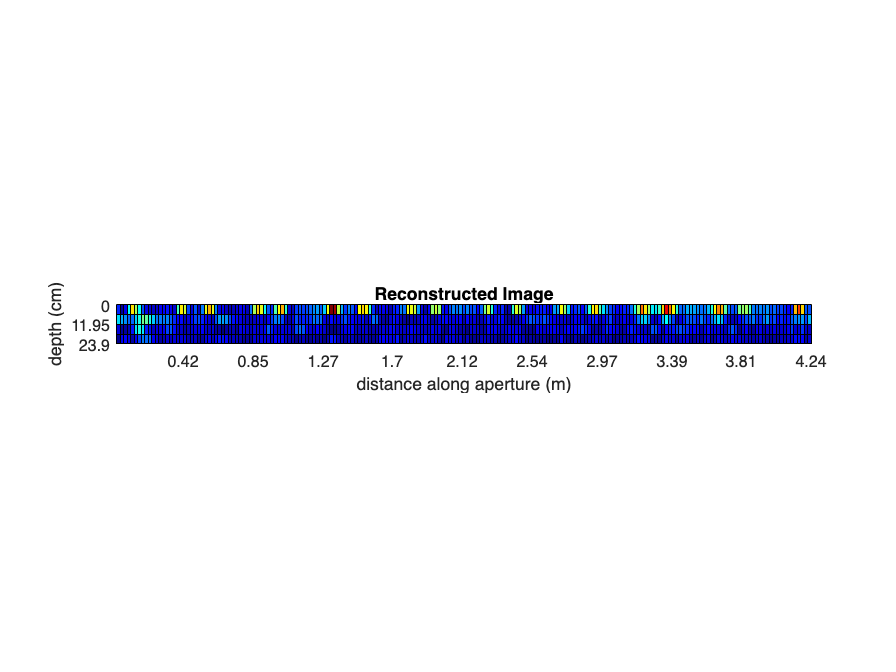

%% params
range_lim = 0.2; % maximum depth of interest in meters
e_r = 6;
D = spacing;
N = length(freqs);
num_xticks = 10;
num_yticks = 3;
speed = c/sqrt(e_r);
bandwidth = freqs(N) - freqs(1);
d_f = bandwidth/N;
resolution_increase = 3;

%% resolution
range = 0.5*speed/d_f;
range_resolution = range/N;
index_lim = ceil(range_lim/range_resolution);
%% recontruct and display image
F_n = zeros(size(F));
for i = 1:length(da)
    F_n(:,i) = abs(fft(F(:,i),N));
end
figure;
pcolor(F_n)
colormap(jet)
ylim([W-index_lim W])
daspect([range_resolution D 1]);
title('Reconstructed Image')
xlabel('distance along aperture (m)')
ylabel('depth (cm)')

xticks = zeros([1,num_xticks]);
for i = 1:length(xticks)
    xticks(i) = round(i*span/num_xticks,2);
end
xticklabels(xticks)
yticks = zeros([1,num_yticks]);
for i = 1:length(yticks)
    yticks(i) = round((num_yticks - i)*range_resolution*200,2);
end
yticklabels(yticks)

## zero padding

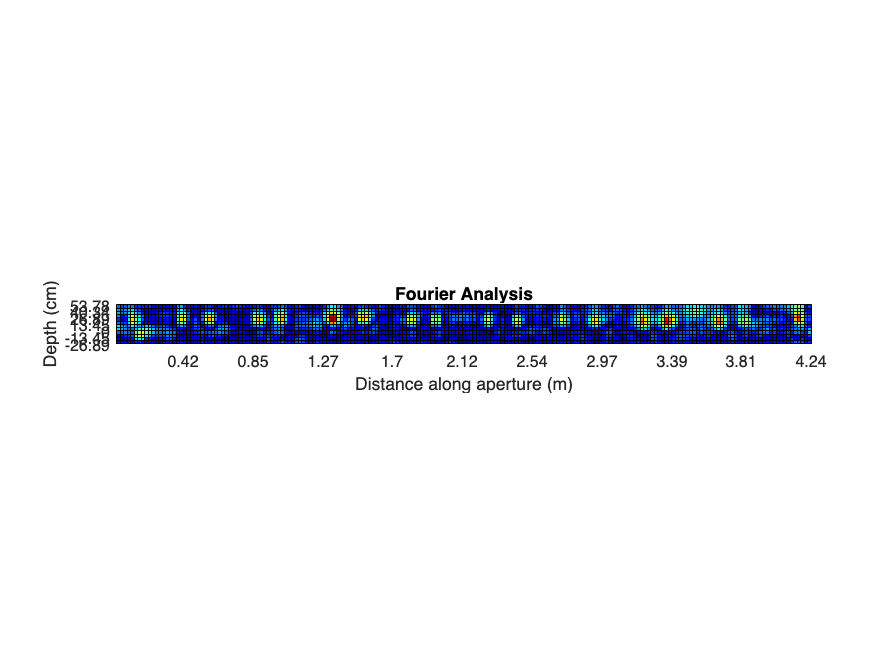

F_padded = F;
for i = 1:N
    F_padded(resolution_increase*N,i) = 0;
end
%% recontruct and display higher resolution image
F_n_padded = zeros(size(F_padded));
for i = 1:length(da)
    F_n_padded(:,i) = abs(fft(F_padded(:,i),resolution_increase*N));
end
figure;
pcolor(F_n_padded)
colormap(jet)
ylim([resolution_increase*N-resolution_increase*index_lim resolution_increase*N])
daspect([range_resolution/resolution_increase D 1]);
title('Fourier Analysis')
xlabel('Distance along aperture (m)')
ylabel('Depth (cm)')
xticks = zeros([1,num_xticks]);
for i = 1:length(xticks)
    xticks(i) = round(i*span/num_xticks,2);
end
xticklabels(xticks)
yticks = zeros([1,num_yticks]);
for i = 1:length(yticks)+4
    yticks(i) = round(-1*((num_yticks - i)*range_resolution*225),2);
end
yticklabels(yticks)